## Transducer modelling:

 **Sittig Transfer matrix:**

clear all
x=1;


## variables

w=linspace(0,2*pi*2*10^7,100000)   % System angular frequency in rad/s

w = 	1.0e+08 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006



a=2.5*10^-3;                     % Radius of the piezoelectric plate
rho=7.8*10^3;                    % Piezoelectric plate density
c_33=16.6*10^10;                 % Elastic constant of the plate
d=2*10^-3;                       % plate thickness
Z_b=x*w                         % Acoustic impedance of the backing plate (this is a function of frequency)

Z_b = 	1.0e+08 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006


d_33=265*10^-12;                 % Piezoelectric charge coefficient
s_33=14.2*10^-12;                % Elastic compliance coefficient
epsilon_0=8.854*10^-12;          % Vacuum permitivity
epsilon_33=1200*epsilon_0;       % relativity Permativity
Beta_33= epsilon_0/epsilon_33;   % the dielectric impermeability of the plate at constant strain,
c=1300;                          % compresisonal wave speed in fluid                     
h_33= d_33/(s_33*epsilon_33);    % Piezoelectric stiffness constant for the plate
v_o=sqrt(c_33/rho);              % compressional wave speed from piezoelectric
k=w/v_o                         % wave number for the peizoelectric plate

k = 	1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013


S=pi*a^2;                        % Piezoelectric surface area
C_o=S/(Beta_33*d);               % the clamped capacitance of the plate
n=h_33*C_o;                      % A given constant
S_a=S;                           % effective face area of the transducer
rho_2=857;                       % density of the fluid
Kin_Vis=32*10^-6;                % Kinematic Viscosity of the fluid (ISO VG 32)
Vis=Kin_Vis*rho_2;               % Dynamic viscosity of the fluid

Z_o=rho*v_o*S;                   % plane wave acoustic impedance of the piezoelectric plate
c_2=3230;                        %Speed of sound in steel
rho_3=7850;                      %Density of steel
R=((c*rho_2)-(c_2*rho_3))/((c*rho_2)+(c_2*rho_3)); %Reflection coefficient 
L=0.00448;                        %Lentgh of chamber

k_2=w/c_2                       % wave number of the coating material of the transducer source

k_2 = 	1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0018    0.0019    0.0019


d_2=0.5*10^3;                    % thickness of the coating material of the transducer source
S_m=(4.5*10^3)^2*pi;             % Face area of the coating material fo the transducer soruce
Z_m=rho_3*c_2*S_m;               % The acoustic impedance of the coating material of the transducer source

## Matrix equations




TAe_matrix = zeros(length(w),2);
TAa_matrix = zeros(length(w),2);
TAl_matrix = zeros(length(w),2);
TA_matrix = zeros(length(w),2);

for p=1:length(w)
    
    steps1 = 2*p - 1;
    steps2 = 2*p;
    
TAe_matrix(steps1:steps2,1:2) =[1/n n/(1i*w(p)*C_o); -1i*w(p)*C_o 0];         %Transducer electrical matrix
TAa_matrix(steps1:steps2,1:2) =(1/(Z_b(p)-1i*Z_o*tan((k(p))*d/2)))*[Z_b(p)+1i*Z_o*cot(k(p)*d) (Z_o)^2+1i*Z_o*Z_b(p)*cot(k(p)*d); 1 Z_b(p)-2*1i*Z_o*tan(k(p)*d/2)];     %Transducer acoustic matrix

TAl_matrix(steps1:steps2,1:2)=[cos(k_2(p)*d_2) -1i*Z_m*sin(k_2(p)*d_2); (-1i*sin(k_2(p)*d_2))/Z_m cos(k_2(p)*d_2)]; 

TA_matrix(steps1:steps2,1:2) = TAe_matrix(steps1:steps2,1:2)*TAa_matrix(steps1:steps2,1:2)*TAl_matrix(steps1:steps2,1:2) ; %Sittig model matrix



end




**Solving for sensitivity **$S_{\textrm{vI}}$**:**

Z_r=S_a*rho_2*c;         % Acoustic radiation impedance

S_vI = zeros(length(w),1);

for kl = 1:length(w)
    
    ste2 = 2*kl;
  S_vI(kl)=1/(Z_r*TA_matrix(ste2,1)+TA_matrix(ste2,2)); %Sensitivity for vI.  
end


**Transducer electrical impedance :**

Z_in = zeros(length(w),1);

for wen = 1:length(w)
ste3 = 2*wen-1;
ste4 = 2*wen;
Z_in(wen) =(Z_r*TA_matrix(ste3,1)+TA_matrix(ste3,2))/(Z_r*TA_matrix(ste4,1)+TA_matrix(ste4,2)); %Electrical impedance of the transducer
end

**Final transfer function **$S_{\textrm{FV}}$**:**

S_FV = zeros(length(w),1)

S_FV =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for phi = 1:length(w)
 S_FV(phi) =Z_r*S_vI(phi)/Z_in(phi); %Sensitivity FV  
end

S_FV_DB=20*log10(abs(S_FV))

S_FV_DB =        NaN
 -326.1780
 -319.8810
 -315.8904
 -312.7173
 -309.8778
 -307.1335
 -304.3234
 -301.2984
 -297.8690


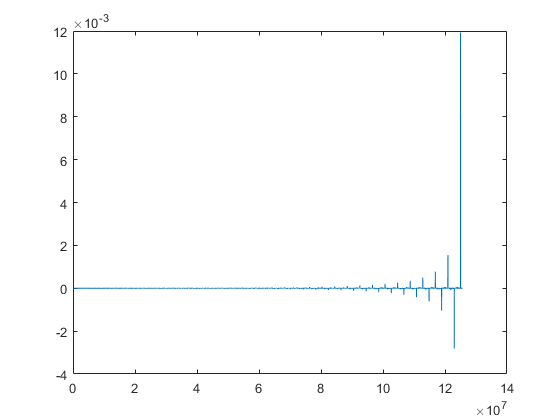

plot(w,S_FV)

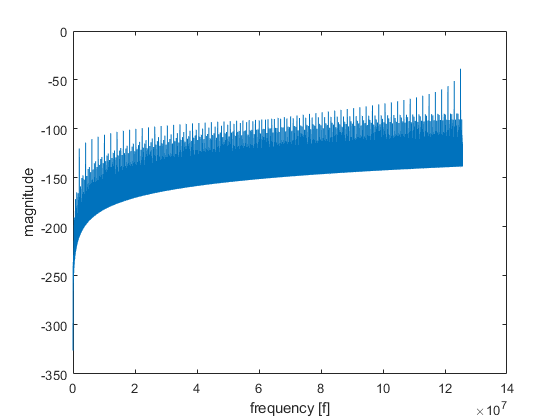

plot(w,S_FV_DB)
xlabel('frequency [f]')
ylabel(['magnitude'])